clear
clf
I_range = [10 15 20 25 30]; %sweep of window area

colors = ['#FF0000'; '#0000FF'; '#FF0000'; '#0000FF'; '#0000FF'];

JouleperDollar = ones([1, length(I_range)]);

for x = 1:length(I_range)
    I = I_range(x);
    [T_hour,M, cost] = HouseEnergy(I);
    hold on
    plot(T_hour, M(:,1), 'Color', colors(x,:));
    minloc = find(M(:,1)==min(M(:,1)));% find location of the minimum temperature point and mark it on the plot
    plot(T_hour(minloc), M(minloc,1),'*', 'Color', colors(x,:));
    JouleperDollar(x) = trapz(T_hour, M(:,1)) / cost;
end

insideThermalMass = 1.0056e+06

insideThermalMass = 1.0056e+06

insideThermalMass = 1.0056e+06

insideThermalMass = 1.0056e+06

insideThermalMass = 1.0056e+06

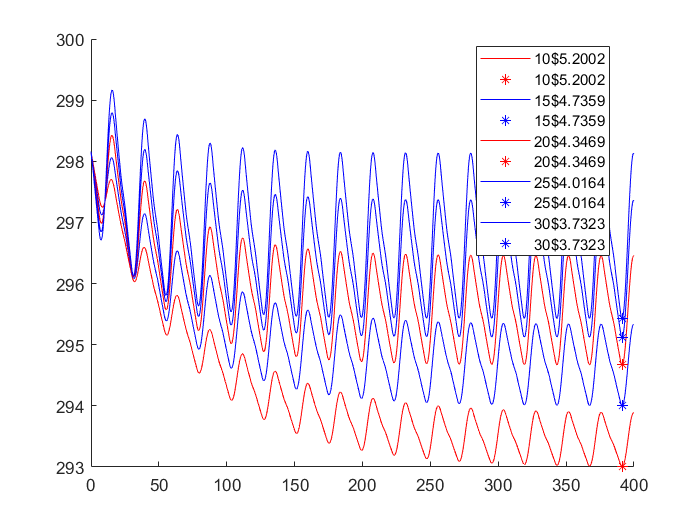


legend(cat(1,string(I_range)+ "$" + string(JouleperDollar),string(I_range)+ "$" + string(JouleperDollar)), "Location","best");

Analysis: Currently, the model is exhibiting unnatural behavior by immediately shooting all stocks towards the energy of the sun. In all seriousness, it seems that my ode is adding energy on to itself instead of updating the stocks. I tried to diagnose and resolve the error myself, but was not able to. Office hours were also canceled so I will go to the next available. Once I have the code done, I will be able to determine the energy per dollar depending on the ratio of area of window to wall. I also do not have a new and improved model as I spent most of my time creating the mathematical equations and since I still do not have a working model, I have not been able to improve it. Even though an extension was requested, we did try to prepare the code to the best of our abilities. 